# Numerical Calculus (2/4)

## 2.3 Mini exercise: Sampling with a bit of noise

The following code generates a sample of u, with a little bit of noise. The noise is a random variable (Gaussian) with standard deviation sigma =0.0001. 

- Make a plot of the first derivative estimate from finite differences.

- Make a plot of the 2nd and 3rd derivatives estimated from finite differences.

- What is the amount of noise (measured by standard deviation) to get all 3 derivatives accurate to within 10% of the true (analytic) value?

Hint: You have numel(tArray) samples for u. How many samples do you have for dudt? How many for du2dt2?

% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

% Take the sample and add a bit of noise
 uObserved = u(tArray) + (1e-7)*randn(size(tArray));
display(uObserved);

uObserved =     0.0100    0.0330    0.0560    0.0789    0.1019    0.1248    0.1476    0.1704    0.1931    0.2157    0.2383    0.2607    0.2831    0.3053    0.3274    0.3493    0.3711    0.3927    0.4142    0.4355    0.4566    0.4775    0.4982    0.5187    0.5390    0.5591    0.5789    0.5984    0.6177    0.6368    0.6555    0.6740    0.6922    0.7101    0.7276    0.7449    0.7619    0.7785    0.7948    0.8107    0.8263    0.8415    0.8564    0.8709    0.8850    0.8988    0.9121    0.9251    0.9376    0.9498


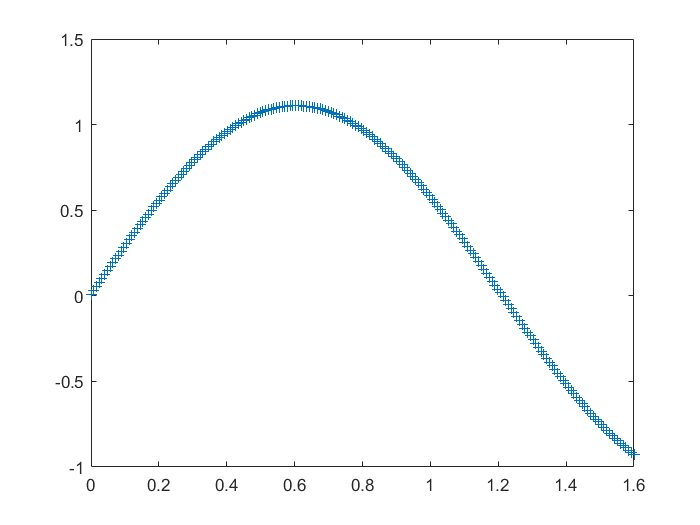

figure;
plot(tArray,uObserved, '+')

## Partial solution below

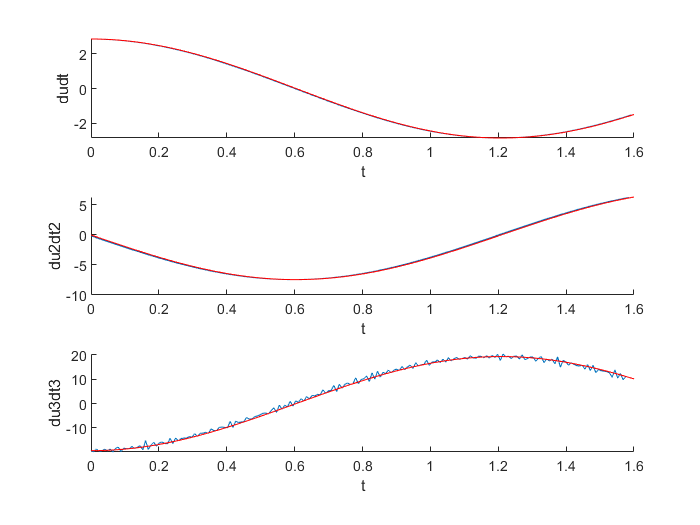

% create finite-difference derivatives for first derivative, second derivative and third derivative
dudt   = diff(uObserved)./diff(tArray);
du2dt2 = diff(dudt)./diff(tArray(1:end-1));
du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));

% and plot them
figure;
subplot(3,1,1); hold on;
plot(tArray(1:end-1), dudt);
plot(tArray, dudtExact, '-r');
xlabel('t');
ylabel('dudt');

subplot(3,1,2); hold on;
plot(tArray(1:end-2), du2dt2);
plot(tArray, du2dt2Exact, '-r');
xlabel('t');
ylabel('du2dt2')

subplot(3,1,3); hold on;
plot(tArray(1:end-3), du3dt3);
plot(tArray, du3dt3Exact, '-r');
xlabel('t');
ylabel('du3dt3')

What is the amount of noise (measured by standard deviation) to get all 3 derivatives accurate to within 10% of the true (analytic) value?

dudterror = max(abs(abs(dudtExact(1:end-1)-dudt)./dudtExact(1:end-1)))*100

dudterror = 353.1825

d2udt2error = max(abs(abs(du2dt2Exact(1:end-2)-du2dt2)./du2dt2Exact(1:end-2)))*100

d2udt2error = Inf

d3udt3error = max(abs(abs(du3dt3Exact(1:end-3)-du3dt3)./du3dt3Exact(1:end-3)))*100

d3udt3error = 2.0397e+03




% room = dudtExact(1:end-1)*.1;
% test = abs(dudt - dudtExact(1:end-1))
% c=0;
% if abs(dudt - dudtExact(1:end-1)) > room
%     c=1;
% end
% c







% noise = linspace(1e-200,1e-2000,20);
% n=length(noise);
% tArray = linspace(0,1.6,20);
% k = zeros(1,n);
% x = k;
% 
% dudtExact      =  A*omega*cos(omega*tArray);
% du2dt2Exact    = -A*omega^2*sin(omega*tArray);
% du3dt3Exact    = -A*omega^3*cos(omega*tArray);
% 
% for i=1:n
%     check = 0;
%     uO(i,:) = u(tArray) + noise(i)*randn(size(tArray));
% %     devs(i) = std(uO(i,:));
%     mydudt(i,:)   = diff(uO(i,:))./diff(tArray);
%     
%     room1 = max(dudtExact(1:end-1)*.1);
% %     test1(i,:) = abs(dudtExact(1:end-1) - mydudt(i,:))
%     if abs(max((dudtExact(1:end-1)) - std(mydudt(i,:)))) > (room1+max((dudtExact(1:end-1))))
%         check = 1
%     end
%     mydu2dt2(i,:)  = diff(mydudt(i,:))./diff(tArray(1:end-1));
%     room2 = max(du2dt2Exact(1:end-2)*.1);
%     if max(abs(du2dt2Exact(1:end-2) - mydu2dt2(i,:))) > room2
%         check = 2
%     end
%     mydu3dt3(i,:)  = diff(mydu2dt2(i,:))./diff(tArray(1:end-2));
%     room3 = max(du3dt3Exact(1:end-3)*.1);
%     if max(abs(du3dt3Exact(1:end-3) - mydu3dt3(i,:))) > room3
%         check = 3
%     end
%     if check == 0;
%         k(i) = noise(i);
%     end
% end
k

k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
